% Numerical analysis - exercise 2
clear
format shortG
% in the exercise, the problems are numbered 1 1 2 3 4 5

% Problem 1.1
% y = c1*exp(c2*t)
% ln(y) = ln(c1) + c2*t
% ln(y) = k + c2*t with c1 = exp(k)
y = [1;2;2;5];
A = [1,-2;1,0;1,1;1,2];
lny = log(y);
kc2 = inv(A'*A)*A'*lny;
c = [exp(kc2(1)); kc2(2)]

c =         1.932
       0.3615


% Problem 1.2
%a
syms u v
f(u,v) = [(u^3 - v^3 + u), (u^2 + v^2-1)]';
J = jacobian(f, [u,v]);
x0 = [1; 1];
sol1 = newton(f, J, x0, 10^(-9))

$$sol1(u, v) = \left(\begin{array}{c} 0.50799\\ 0.86136 \end{array}\right)$$


x0 = [-1; -1];
sol2 = newton(f, J, x0, 10^(-9))

$$sol2(u, v) = \left(\begin{array}{c} -0.50799\\ -0.86136 \end{array}\right)$$

%b
syms u v w
f(u,v,w) = [(2*u^2 - 4*u + v^2 + 3*w^2 + 6*w + 2)...
            ,(u^2 + v^2 - 2*v + 2*w^2 - 5)...
            ,(3*u^2 - 12*u + v^2 + 3*w^2 + 8)]';
J = jacobian(f, [u,v, w]);
x0 = [2; 1.5; -1.5];
sol1 = newton(f, J, x0, 10^(-5))

$$sol1(u, v, w) = \left(\begin{array}{c} 2.0\\ 1.0\\ -1.0 \end{array}\right)$$


x0 = [-1; -1; -1];
sol2 = newton(f, J, x0, 10^(-5))

$$sol2(u, v, w) = \left(\begin{array}{c} 1.09602\\ -1.15925\\ -0.26115 \end{array}\right)$$

% Problem 2
% y = c1*t*exp(c2*t)
% ln(y) = ln(c1) + ln(t) + c2*t
% ln(y) - ln(t) = k + c2*t (c1 = exp(k))
t = (1:10)';
y = [6.2;9.5;12.3;13.9; 14.6;13.5;13.3;12.7;12.4;11.9];
b = log(y) - log(t);
A = [ones(10,1) t];
kc2 =  inv(A'*A)*A'*b;
c = [exp(kc2(1)); kc2(2)]

c =         7.122
     -0.18385


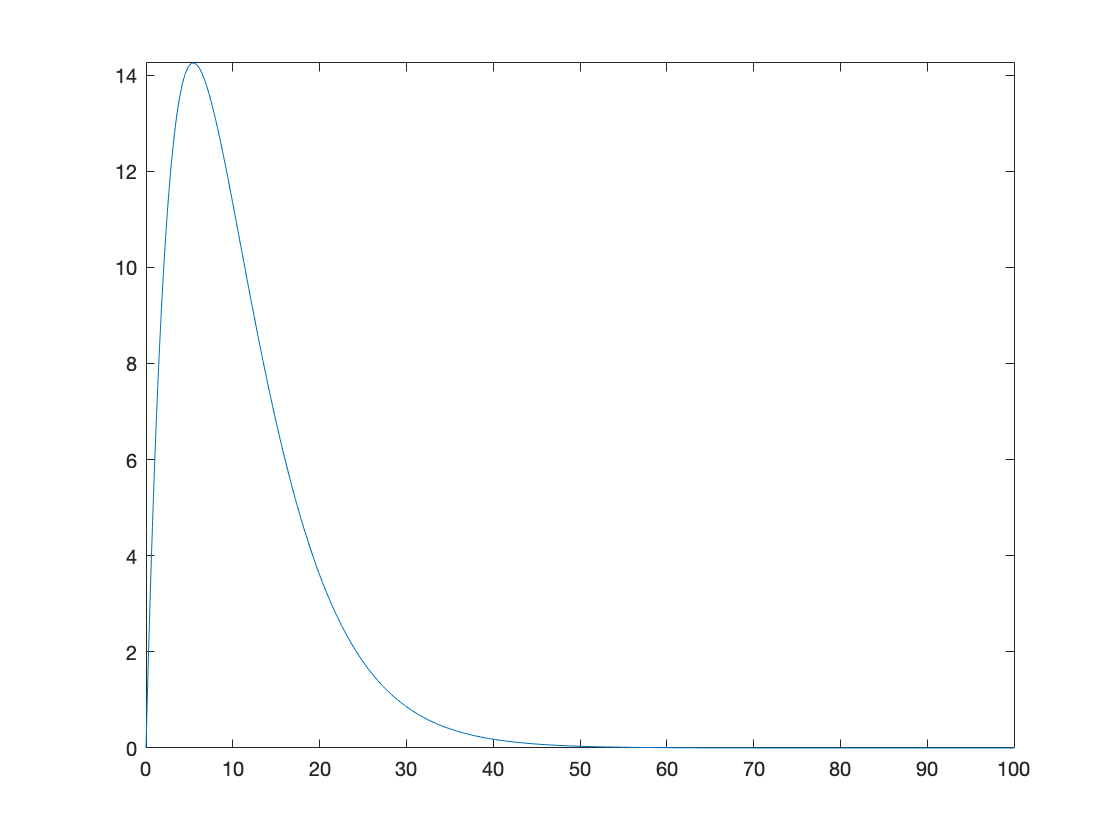


x_new = (0:0.001:100);
y_hat = c(1).*x_new.*exp(c(2)*x_new);
plot(x_new,y_hat)
axis tight


% find max of y = 7.122*t*exp(-0.18385*t)
syms x
f(x) = c(1)*x*exp(c(2)*x);
df = diff(f);
xmax = round(solve(df == 0, x), 5)

$$xmax = 5.43925$$

% max y
round(f(xmax), 5)

$$ans = 14.25108$$


% find x when f = 4
x1 = bisec(f - 4, 0, 1, 10^-8)

x1 =       0.63069


x2 = bisec(f - 4, 10,30,10^-8)

x2 =        19.214


% so, when x1<t<x2, the drug concentration stay within therapeutic level.

% Problem 4
% c) d = 6
x0=[0 1 2 3 4 5 6];
y0=[-2 1 1 4 4 3 -2];
c=newtdd(x0,y0,7)

c =            -2
            3
         -1.5
            1
         -0.5
      0.16667
    -0.045833


syms x
f(x) = -2 + 3*x -1.5*x*(x-1) + x*(x-1)*(x-2) -0.5*x*(x-1)*(x-2)*(x-3)...
    + (1/6)*x*(x-1)*(x-2)*(x-3)*(x-4) -(11/240)*x*(x-1)*(x-2)*(x-3)*(x-4)*(x-5);
f([0 2 4])

$$ans = \left(\begin{array}{ccc} -2 & 1 & 4 \end{array}\right)$$

simplify(f)

$$ans(x) = -\frac{11\,x^{6}}{240}+\frac{41\,x^{5}}{48}-\frac{97\,x^{4}}{16}+\frac{967\,x^{3}}{48}-\frac{3707\,x^{2}}{120}+19\,x-2$$

% Problem 5
%3a i
x0=[0 2 3];
y0=[1 3 0];
c=newtdd(x0,y0,3)

c =             1
            1
      -1.3333


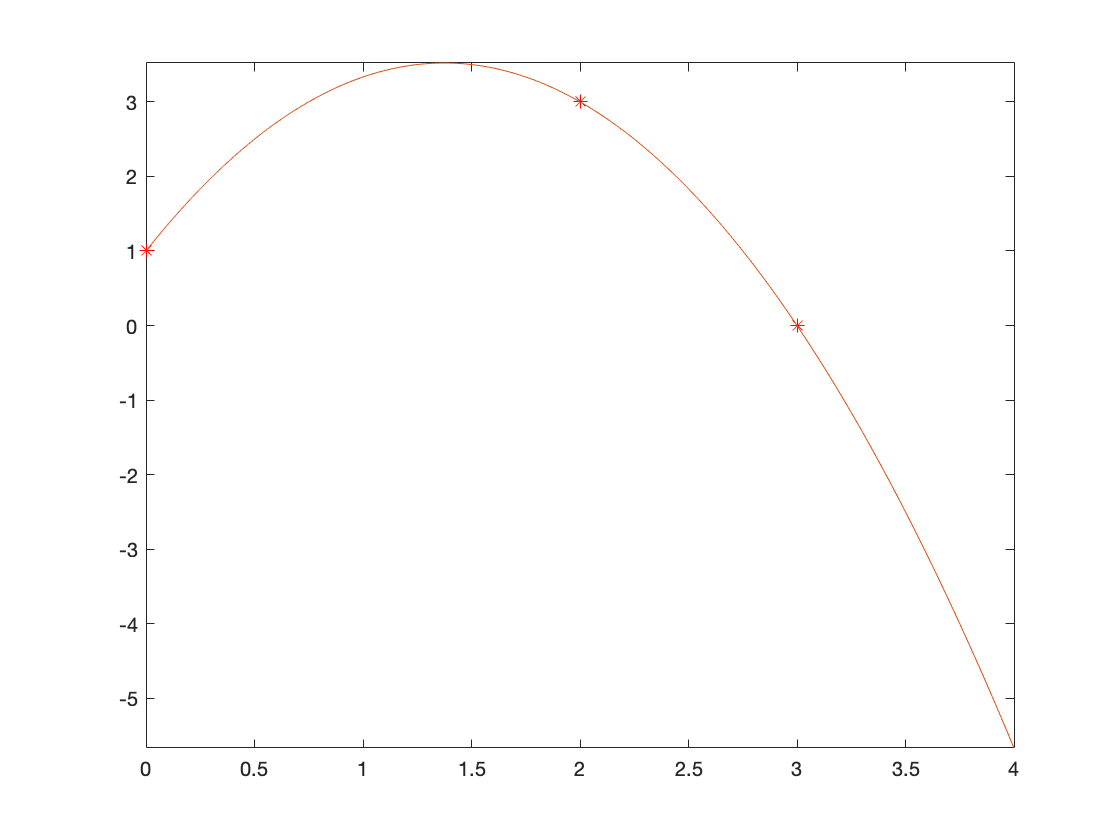

x=0:.001:4;
y = c(1) + c(2)*(x - x0(1)) + c(3)*(x - x0(1)).*(x - x0(2));
% y = 1 + x - (4/3)(x)(x - 2)
% y = 1 + x - (4/3)(x^2 -3x +2)
% y = 1 + (11/3)x - (4/3)x^2
% similar to the Lagrange interpolation methods
plot(x0,y0, "r*" ,x,y)
axis tight

%3a ii
x0=[0 2 4];
y0=[-2 1 4];
c=newtdd(x0,y0,3)

c =            -2
          1.5
            0


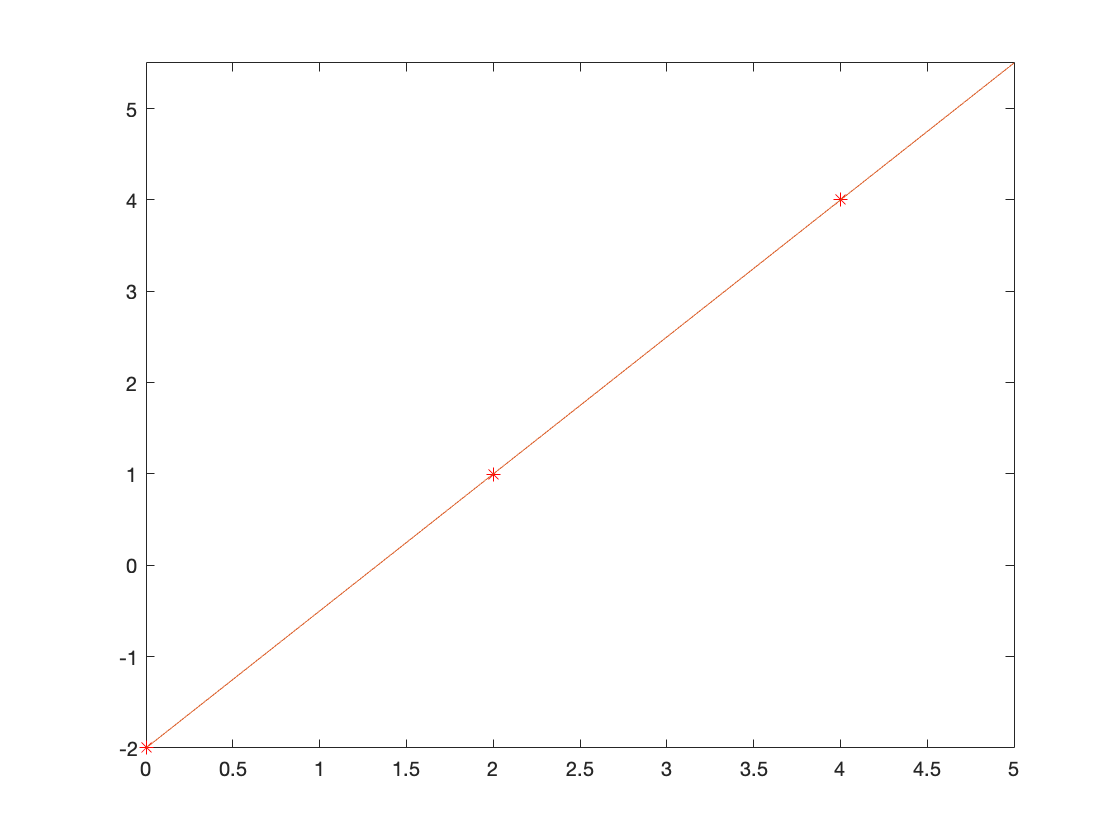

x=0:.001:5;
y = c(1) + c(2)*(x - x0(1)) + c(3)*(x - x0(1)).*(x - x0(2));
% y = -2 + 3/2(x-0) + 0
% y = -2 + (3/2)x
% similar to the Lagrange interpolation methods
plot(x0,y0, "r*" ,x,y)
axis tight

function [result] = newton(f, J, x0, tol) % Newton method
var = symvar(f)';
result = x0;
Jx = subs(J, var, result);
fxk = subs(f, var, result);
s = linsolve(Jx, -fxk);
x1 = result + s;
e = x1 - x0;

while (norm(e) > tol)
    e = inv(Jx)*fxk;
    Jx = subs(J, var, result);
    fxk = subs(f, var, result);
    s = linsolve(Jx, -fxk);
    result  = result + s;
end

result = round(result, 5);
end

function [result] = bisec(f, a, b, tol)
% a b is the search range [a,b]
% f(x) is the function
% tol is tolerance error
result = Inf;
if (f(a)*f(b) < 0)
    while ((b-a)/2 > tol)
        c = (a + b)/2;
        if f(c) == 0
            result = c;
            break
        end
        
        if (f(a) * f(c)<0)
            b = c;
        else 
            a = c;
        end
    end
    result = c;
end
end

% Newton's Divided Diferences
function c=newtdd(x,y,n)
v = zeros(n);
c = zeros(n,1);

for j=1:n
    v(j,1)=y(j);
end

for i=2:n
for j=1:n+1-i
v(j,i)=(v(j+1,i-1)-v(j,i-1))/(x(j+i-1)-x(j));
end
end

for i=1:n
c(i)=v(1,i);
end

end